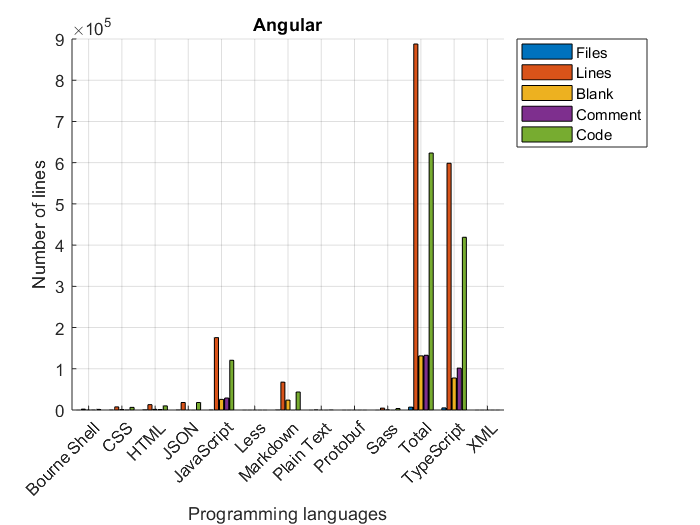

clear vars

table_angular = readtable("angular_loc_data.xlsx");


% Angular start

data_start_column = 2;
data_end_column = 6;

figure
hold on
colormap summer;

headers = table_angular.Properties.VariableNames(:,data_start_column:data_end_column);
x = table_angular.Language';
x = categorical(x);
y = table_angular{:,data_start_column:data_end_column};

files_angular = y(size(y,1), 1);
loc_angular = y(size(y,1),size(y,2));

bar(x, y);
grid on
ylabel('Number of lines');
% yticks([0 100000 1000000]);
xlabel('Programming languages');
title('Angular');
legend(headers, "Location", "northeastoutside");

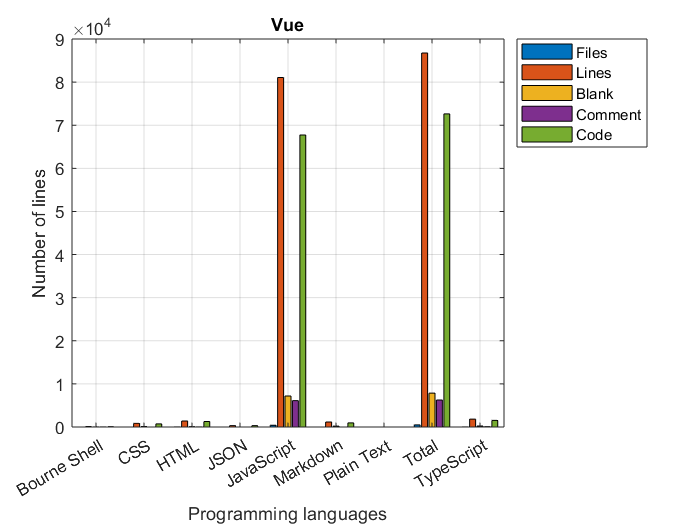


% Angular end


% Vue start

table_vue = readtable("vue_loc_data.xlsx");

figure
x = table_vue.Language';
x = categorical(x);
y = table_vue{:,data_start_column:data_end_column};

files_vue = y(size(y,1), 1);
loc_vue = y(size(y,1),size(y,2));

bar(x, y);
grid on
ylabel('Number of lines');
xlabel('Programming languages');
title('Vue');
legend(headers, "Location", "northeastoutside");

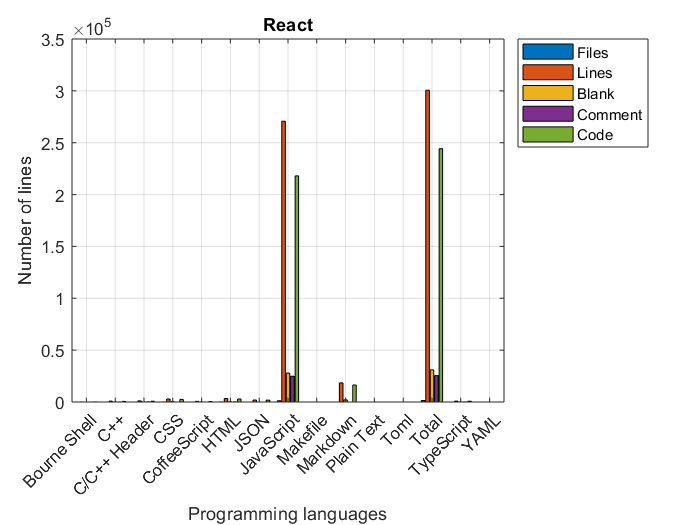


% Vue end


% React start

table_react = readtable("react_loc_data.xlsx");

figure
x = table_react.Language';
x = categorical(x);
y = table_react{:,data_start_column:data_end_column};

files_react = y(size(y,1), 1);
loc_react = y(size(y,1),size(y,2));

bar(x, y);
grid on
ylabel('Number of lines');
xlabel('Programming languages');
title('React');
legend(headers, "Location", "northeastoutside");

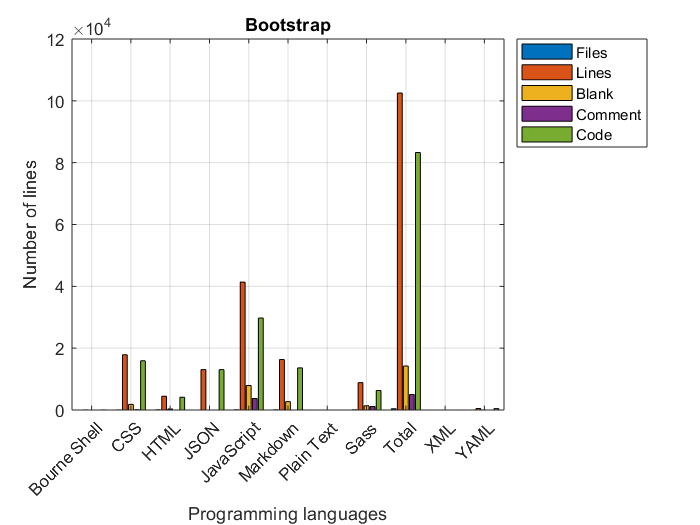


% React end


% Bootstrap start

table_bootstrap = readtable("bootstrap_loc_data.xlsx");

figure
x = table_bootstrap.Language';
x = categorical(x);
y = table_bootstrap{:,data_start_column:data_end_column};

files_bootstrap = y(size(y,1), 1);
loc_bootstrap = y(size(y,1),size(y,2));

bar(x, y);
grid on
ylabel('Number of lines');
xlabel('Programming languages');
title('Bootstrap');
legend(headers, "Location", "northeastoutside");

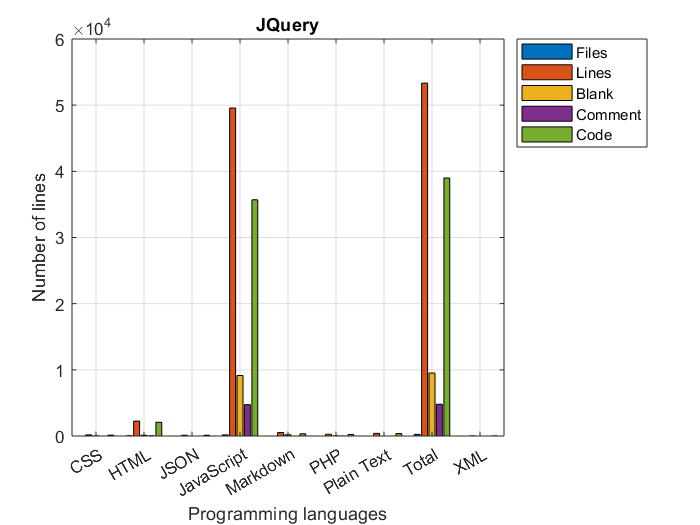


% Bootstrap end


% JQuery start

table_jquery = readtable("jquery_loc_data.xlsx");

figure
x = table_jquery.Language';
x = categorical(x);
y = table_jquery{:,data_start_column:data_end_column};

files_jquery = y(size(y,1), 1);
loc_jquery = y(size(y,1),size(y,2));

bar(x, y);
grid on
ylabel('Number of lines');
xlabel('Programming languages');
title('JQuery');
legend(headers, "Location", "northeastoutside");

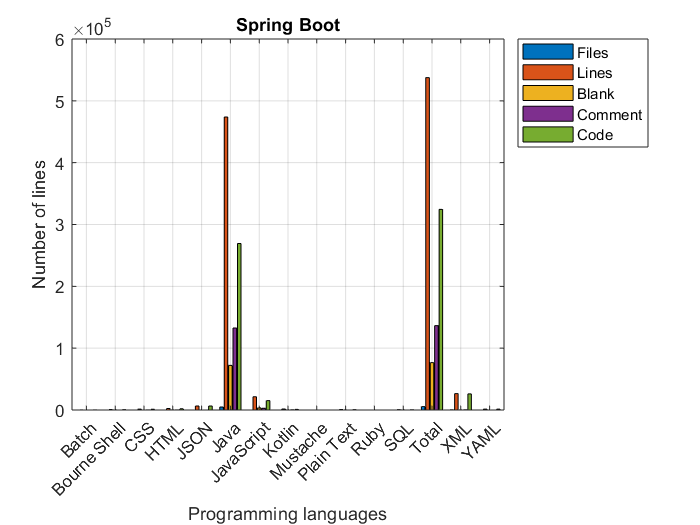


% JQuery end


% Spring Boot start

table_springboot = readtable("spring-boot_loc_data.xlsx");

figure
x = table_springboot.Language';
x = categorical(x);
y = table_springboot{:,data_start_column:data_end_column};

files_springboot = y(size(y,1), 1);
loc_springboot = y(size(y,1),size(y,2));

bar(x, y);
grid on
ylabel('Number of lines');
xlabel('Programming languages');
title('Spring Boot');
legend(headers, "Location", "northeastoutside");

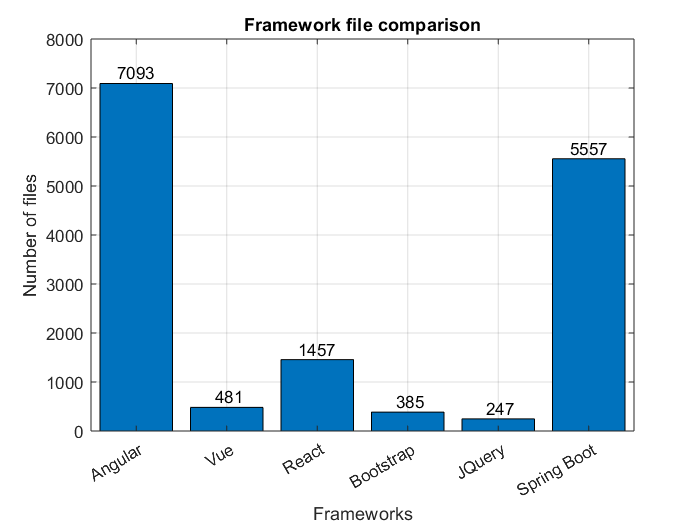


% Spring Boot end


% Files per framework start

figure
framework_headers = categorical(["Angular" "Vue" "React" "Bootstrap" "JQuery" "Spring Boot"]);
framework_headers = reordercats(framework_headers, ["Angular" "Vue" "React" "Bootstrap" "JQuery" "Spring Boot"]);
files_y_values = [files_angular files_vue files_react files_bootstrap files_jquery files_springboot];
b = bar(framework_headers, files_y_values);
text(1:length(files_y_values), files_y_values, num2str(files_y_values'), "vert", "bottom", "horiz", "center");
grid on
ylabel('Number of files');
xlabel('Frameworks');
title('Framework file comparison');

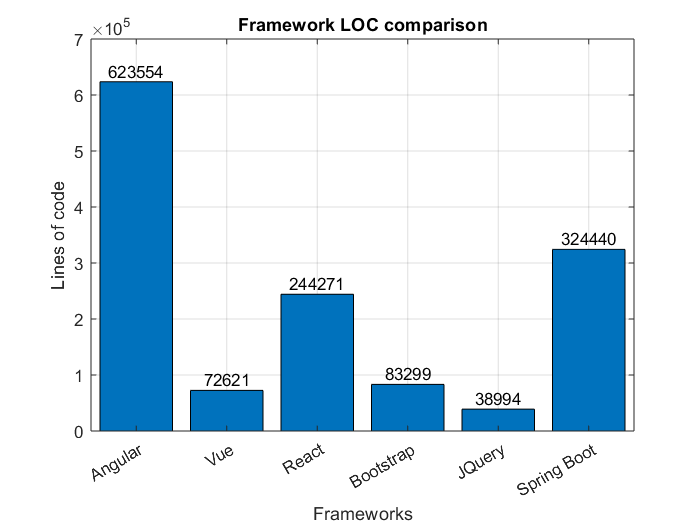


% Files per framework end

% loc per framework start

colors = ["r" "g" "b" "m" "c" "k"];

figure
framework_headers = categorical(["Angular" "Vue" "React" "Bootstrap" "JQuery" "Spring Boot"]);
framework_headers = reordercats(framework_headers, ["Angular" "Vue" "React" "Bootstrap" "JQuery" "Spring Boot"]);
files_y_values = [loc_angular loc_vue loc_react loc_bootstrap loc_jquery loc_springboot];
bar(framework_headers, files_y_values);
text(1:length(files_y_values), files_y_values, categorical(files_y_values'), "vert", "bottom", "horiz", "center");
grid on
ylabel('Lines of code');
xlabel('Frameworks');
title('Framework LOC comparison');


% loc per framework end

hold off